# Simulate box's trajectory and track it 

Specifying all parameters, boh for simulation (_sim) and for the Extended Kalman Filter

%rng(1);    % For repeatable results
dt = 0.005;     % seconds
simTime = 1; % seconds
tspan   = 0:dt:simTime;

m=0.3;%Kg for the box
m_sim=0.3;%Kg
m_ee=2;%Kg for the end effector's mass, equivalent to inertia
m_ee_sim=2;
mu=0.3;%Coefficient of friction
mu_sim=0.3;
g=-9.81;%N/Kg gravity
restit = 0.7;%Restitution factor
restit_sim = 0.7;

flux = 1;%m/s, Define the flux for the hit
flux_sim=1;
V_EE = flux * (1 + (m_sim/m_ee_sim))/(1+restit_sim);%Get the end-effector speed required to achieve target flux

sigma_2=0.01; %Standard deviation
sigma_1= m*((1+restit)^2 * flux^2) / (2 * sigma_2 * sqrt(2*pi)); %Max amplitude of the Hitting force
sigma_1

sigma_1 = 17.2941


X_0 = 0;%Initial position of box
D_0 = 0.1;%Initial distance

Impulse_type = 0;%0 for impulse, 1 for gaussian

trueInitialState = [X_0; 0; 0; D_0; V_EE; 0]; % [x;vx;f;d;v_ee;fh]
processNoise = diag([0; 0; 0; 0; 0 ; 0]); % No process noise in this model, but from report : Process noise matrix diag([0.01; 0.1; 0.14; 0.01])
%measureNoise = 0.005^2; % Measurement noise matrix

numSteps = length(tspan);
trueStates = NaN(6,numSteps);
trueStates(:,1) = trueInitialState;



## Obtain True States and Measurements

Propagate the constant velocity model, and generate the measurements with noise. 

%Note that the total force transmitted through impact is equal to :
%Integral Fh over d = sigma_1 * sigma_2 * sqrt(2*pi)

% [x;vx;f;d;v_ee;fh]
A = [1  dt  ((dt^2)/(2*m))  0 0 ((dt^2)/(2*m));
     0  1   dt/m            0 0 dt/m; 
     0  0   1               0 0 0;
     0  dt  0               1 -dt 0;
     0  0   0           0 1 -dt/m_ee;
     0  0   0               0 0 0];
C = [1 0 0 0 0 0];

for i = 2:length(tspan)
    trueStates(:,i) = A*trueStates(:,i-1) + sqrt(processNoise)*randn(6,1);
    if Impulse_type == 1
        trueStates(6,i) = sigma_1 * exp(-(trueStates(4,i)^2)/(2*sigma_2^2)); %Modulate applied force by distance
    else
       if trueStates(4,i)<0
           trueStates(2,i) = (1+restit_sim) * flux_sim;%V+ = (1+restit) * flux
           trueStates(5,i) = (trueStates(2,i)*m) / (m_ee_sim^2 / trueStates(5,i));%Xe+ = m*v+ / m_ee^2*v_ee- 
       end
    end
    if abs(trueStates(2,i)) > 6e-3 %Only if speed is high enough, apply friction ; prevent osicllations around 0 speed
        trueStates(3,i) = mu_sim*g*m_sim*(trueStates(2,i)/abs(trueStates(2,i)));%f=m*g*mu*v/abs(v)
    else trueStates(3,i) = 0;
    end
end
%measurements = C*trueStates + sqrt(measureNoise)*randn(1,numSteps);

Xf = NaN(1,numSteps);
for i = 1:length(tspan)
    Xf(i) = trueStates(1,i) + (0.5 * trueStates(2,i)^2 / (mu * 9.81));
end

Plot the true trajectory

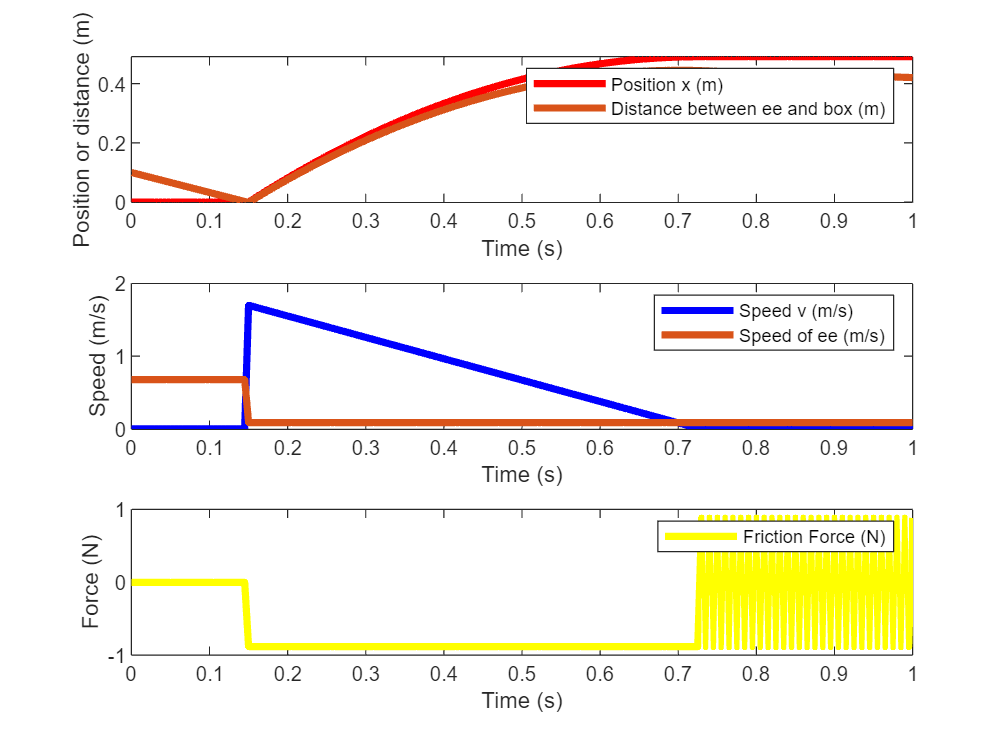

figure
subplot(3,1,1)
plot(tspan,trueStates(1,:),"r",'LineWidth',3,DisplayName="Position x (m)")
hold on
plot(tspan,trueStates(4,:),'LineWidth',3,DisplayName="Distance between ee and box (m)")
ylabel("Position or distance (m)")
xlabel("Time (s)")
legend


subplot(3,1,2)
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Speed v (m/s)")
hold on
plot(tspan,trueStates(5,:),'LineWidth',3,DisplayName="Speed of ee (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend

subplot(3,1,3)
plot(tspan,trueStates(3,:),"y",'LineWidth',3,DisplayName="Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend

## Initialize Extended Kalman Filter

Initialize the filter

n=7;      %number of state
q=0.01;    %std of process 
r=0.005;    %std of measurement
Q=q^2*eye(n); % covariance of process
R=r^2;        % covariance of measurement
phi = flux

phi = 1



%f=@(x)[x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4)));
%       x(2) + (dt/m) * (x(3) + x(4));
%       -m*9.81*mu*sign(x(2));
%       sigma_1*exp(-x(5)^2 / (2*sigma_2^2));
%       x(5) + x(2)*dt];% nonlinear state equations

h=@(x)[x(1);x(5)];                        % measurement equation
s=[X_0;0;0;0;D_0; 0.5; 0.5];              % initial state
x=s+q*randn(n,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

%numSteps = length(tspan);
%trueStates = NaN(6,numSteps); [x;vx;Ff; Fh;d]
%trueStates(:,1) = trueInitialState; 
estimateStates = NaN(n,numSteps);
Xf_pred = NaN(1,numSteps);

for k=1:numSteps
  z = trueStates([1 4],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,phi,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  s = f(s,m,mu,dt,phi,sigma_2) + q*randn(n,1);  % update process 
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (x(6) * 9.81));
end

A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.5165         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.9453
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.5165         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.9453
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.5196         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.0243
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.5462         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6825
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.5100         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.2207
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.5041         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   16.0798
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4938         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.3099
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4968         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.5423
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4830         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   17.6249
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4904         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   16.2910
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4297         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.4303
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4647         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.1731
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4310         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5291
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4400         0         0         0   -2.9430         0
         0         0         0         0   -0.0001         0   18.1197
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4487         0         0         0    2.9430         0
         0         0         0         0   -0.0022         0   17.6120
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4062         0         0         0   -2.9430         0
         0         0         0         0   -0.0004         0   18.6712
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4117         0         0         0   -2.9430         0
         0         0         0         0   -0.0029         0   18.5253
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4394         0         0         0    2.9430         0
         0         0         0         0   -0.2683         0   17.6438
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4199         0         0         0    2.9430         0
         0         0         0         0   -0.5201         0   17.9305
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4248         0         0         0    2.9430         0
         0         0         0         0   -2.9014         0   17.8467
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4277         0         0         0   -2.9430         0
         0         0         0         0   -2.3571         0   18.2592
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4268         0         0         0   -2.9430         0
         0         0         0         0   -7.9549         0   18.1942
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4261         0         0         0   -2.9430         0
         0         0         0         0  -20.9366         0   18.1749
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.4093         0         0         0    2.9430         0
         0         0         0         0 -174.1345         0   17.7594
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    1.3953         0         0         0    2.9430         0
         0         0         0         0 -181.9905         0   18.0194
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3903         0         0         0   -2.9430         0
         0         0         0         0 -260.8385         0   18.1149
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3871         0         0         0   -2.9430         0
         0         0         0         0 -588.3935         0   17.9388
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3962         0         0         0   -2.9430         0
         0         0         0         0 -654.7927         0   18.0660
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3951         0         0         0   -2.9430         0
         0         0         0         0 -812.8243         0   17.9279
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3832         0         0         0   -2.9430         0
         0         0         0         0 -796.6591         0   18.0077
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.3865         0         0         0   -2.9430         0
         0         0         0         0 -630.8377         0   17.9827
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4416         0         0         0   -2.9430         0
         0         0         0         0  -45.3943         0   17.8212
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.4213         0         0         0   -2.9430         0
         0         0         0         0 -333.4058         0   17.8670
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.2083         0         0         0   -2.9430         0
         0         0         0         0 -633.1077         0   18.2217
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.1537         0         0         0   -2.9430         0
         0         0         0         0 -227.9408         0   18.3010
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0160         0         0         0   -2.9430         0
         0         0         0         0  -14.4983         0   18.4635
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.1604         0         0         0   -2.9430         0
         0         0         0         0  -10.1691         0   18.3251
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9392         0         0         0   -2.9430         0
         0         0         0         0   -0.0546         0   18.5216
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0530         0         0         0   -2.9430         0
         0         0         0         0   -0.0155         0   18.4362
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8870         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5553
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9548         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5143
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9678         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5086
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7859         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6083
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9140         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5461
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7536         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6216
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8475         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5823
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8714         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5736
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6394         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6625
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6350         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6649
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A =     1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8585         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5904
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7319         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6314
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6081         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6695
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5859         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6764
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5722         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6806
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4847         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7041
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.3930         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7276
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5471         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6905
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4134         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7221
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5341         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6949
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5559         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6903
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.3761         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7292
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5212         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6987
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6940         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6630
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5651         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6895
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6734         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6676
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6819         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6659
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7333         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6556
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6032         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6817
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6196         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6784
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5135         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6999
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5850         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6851
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6573         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6699
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4652         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7109
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5534         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6915
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6162         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6773
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7233         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6523
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5913         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6838
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6454         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6703
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6701         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6638
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6155         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6783
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6096         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6797
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6500         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6678
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7050         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6508
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5927         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6866
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7441         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6355
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6739         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6601
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7013         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6498
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6659         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6634
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6335         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6765
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6887         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6524
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7211         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6374
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6733         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6602
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6643         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6646
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6797         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6561
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6373         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6798
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6649         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6631
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6739         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6572
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5948         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.7096
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6950         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6390
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7443         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6022
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7231         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6186
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7396         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.6048
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7508         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.5948
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7176         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6251
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7112         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6311
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7284         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6133
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7073         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6359
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7472         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5903
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7631         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5711
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6961         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6556
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7081         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6394
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7584         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5685
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7487         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5827
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7377         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5998
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7019         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6587
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6921         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6756
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7215         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6211
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7080         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6473
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7405         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5799
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7516         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5555
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7418         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5781
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7594         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5348
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7376         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5909
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7308         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6091
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7498         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5546
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7448         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5696
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7419         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5788
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7511         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5474
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7455         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5673
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7401         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5877
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7629         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.4962
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7553         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5284
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7553         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5284
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7371         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6142
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7440         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5800
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7425         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5878
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7548         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5183
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7611         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.4801
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7542         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5243
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7482         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5646
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7567         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5042
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7565         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5054
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7532         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5319
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7534         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5305
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7462         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5958
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7530         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5298
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7584         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.4742
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7536         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5273
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7500         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5698
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7508         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5601
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7540         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5175
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7574         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4685
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7563         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4861
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7627         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5293
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7925         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5949
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7208         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4716
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7442         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5108
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6960         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4376
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8031         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5746
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8260         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6005
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6269         0         0         0    2.9430         0
         0         0         0         0         0         0   18.3847
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6091         0         0         0    2.9430         0
         0         0         0         0         0         0   18.3653
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7695         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5369
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9550         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.7242
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7449         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5174
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8134         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5858
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7214         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4917
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6817         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4498
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8519         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6280
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7868         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5636
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7922         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5688
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7289         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5064
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8613         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6416
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7128         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4906
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7989         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5769
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7756         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5538
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6880         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4685
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6865         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4671
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7857         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5665
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8556         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6329
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7274         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5131
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7488         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5338
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8744         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.6553
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7116         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5049
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6266         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4274
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7990         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5837
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7226         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5171
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7326         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5257
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7247         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5189
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7777         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5632
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7987         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5800
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8199         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5971
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8197         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5970
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7753         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5571
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7650         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5473
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7281         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5082
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7963         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5829
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7564         0         0         0   -2.9430         0
         0         0         0         0         0         0   18.5416
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6938         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4772
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6907         0         0         0    2.9430         0
         0         0         0         0         0         0   18.4739
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7215         0         0         0    2.9430         0
         0         0         0         0         0         0   18.5090
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


## Run Linear Kalman Filter and Show Results

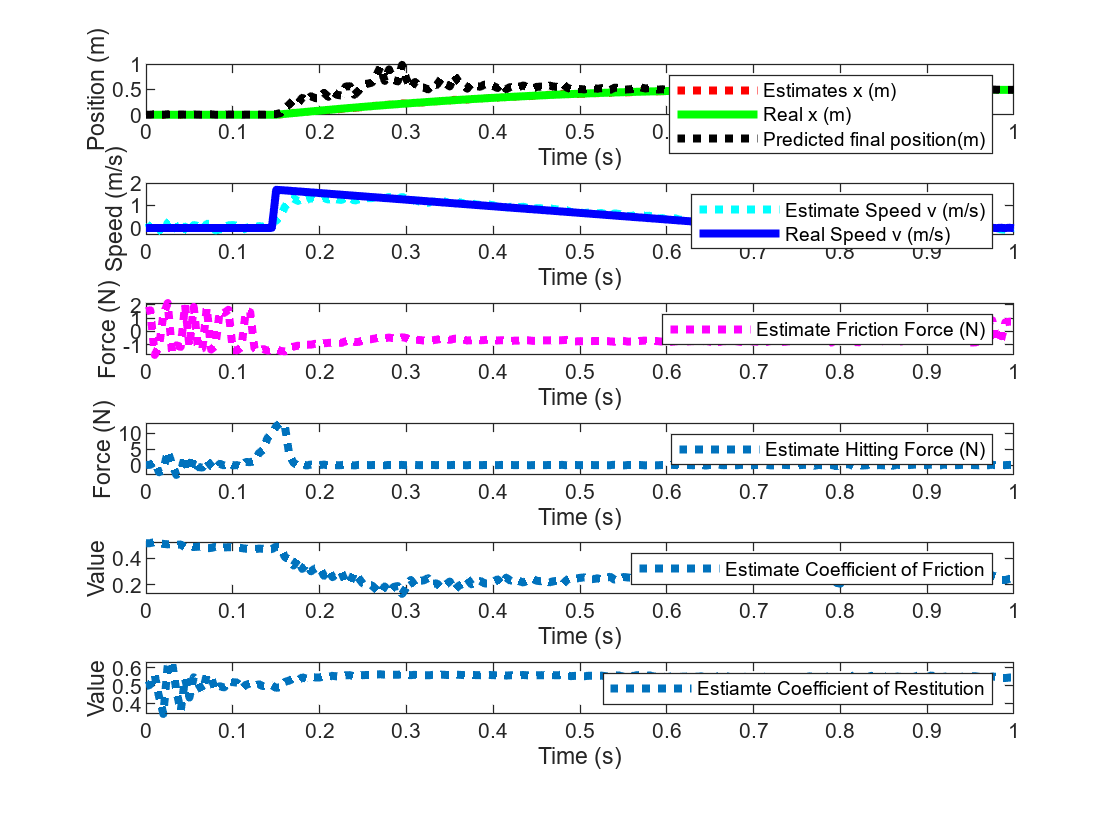

figure

subplot(6,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,3)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,4)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")
subplot(6,1,5)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(6,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Friction")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,6)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(7,:),":",'LineWidth',3,DisplayName="Estiamte Coefficient of Restitution")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

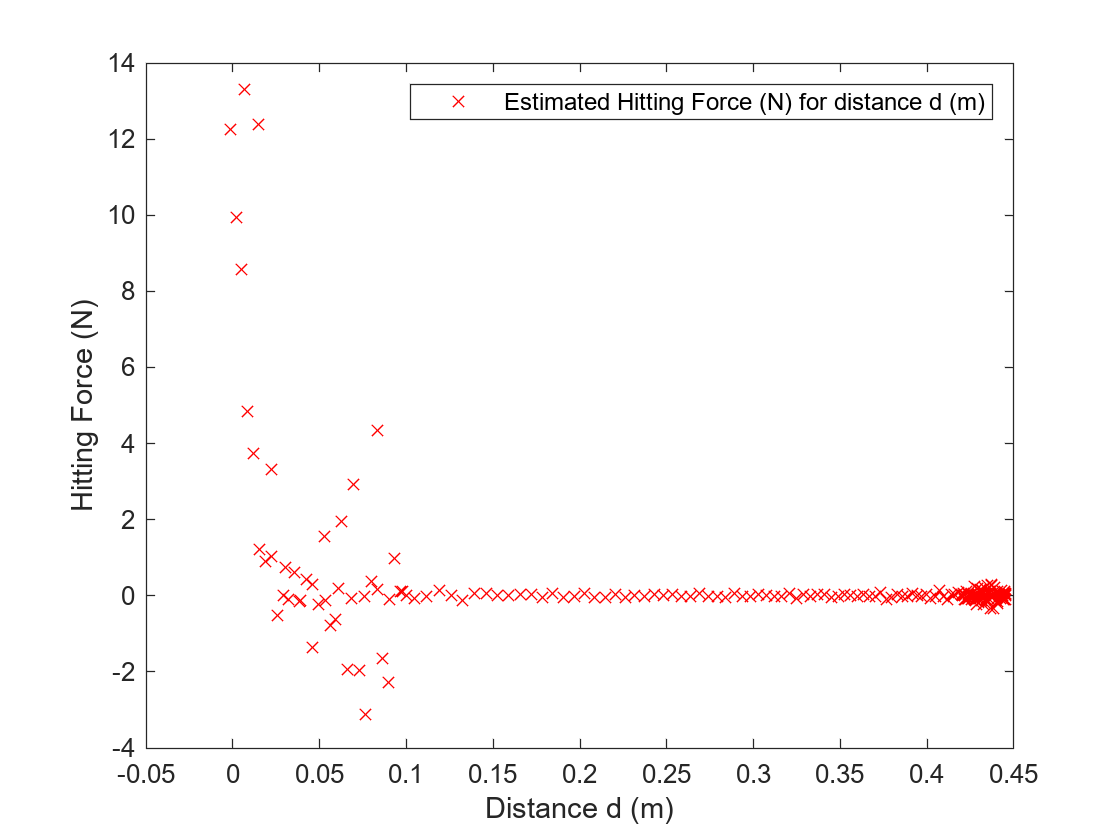




%plot(tspan,Xf,'LineWidth',3,DisplayName="Real final position (m)")

%plot(tspan,trueStates(4,:),'LineWidth',3,DisplayName="Distance between ee and box (m)")
%plot(tspan,estimateStates(5,:),'LineWidth',3,DisplayName="Estimated Distance between ee and box (m)")

figure
plot(trueStates(4,:),estimateStates(4,:),"rx",DisplayName="Estimated Hitting Force (N) for distance d (m)")
%plot(estimateStates(5,:),estimateStates(4,:),"rx",DisplayName="Estimated Hitting Force (N) for distance d (m)")
legend
xlabel("Distance d (m)")
ylabel("Hitting Force (N)")

## Use wrong estimated parameters of the Extended Kalman Filter and Show Results

% %% New parameters for the EKF, different from the simulation
% m=0.3;%Kg for the box
% m_sim=0.3;%Kg
% m_ee=2;%Kg for the end effector's mass, equivalent to inertia
% m_ee_sim=2;
% mu=0.1;%Coefficient of friction
% mu_sim=0.3;
% g=-9.81;%N/Kg gravity
% restit = 0.7;%Restitution factor
% restit_sim = 0.7;
% flux = 1;%m/s, Define the flux for the hit
% flux_sim=1;
% 
% sigma_2=0.01; %Standard deviation
% %sigma_1= m*((1+restit)^2 * flux^2) / (2 * sigma_2 * sqrt(2*pi)); %Max amplitude of the Hitting force
% %sigma_1
% phi = flux

% estimateStates = NaN(n,numSteps);
% Xf_pred = NaN(1,numSteps);
% 
% x=s+q*randn(n,1); %initial state          % initial state with noise
% P = eye(n);                               % initial state covariance
% 
% for k=1:numSteps
%   z = trueStates([1 4],k) + r*randn;        % measurements
%   [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,phi,sigma_2); % ekf 
%   estimateStates(:,k) = x;                % save estimate
%   s = f(s,m,mu,dt,phi,sigma_2) + q*randn(n,1);  % update process 
%   Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (x(6) * 9.81));
% end
% 
% figure
% 
% subplot(6,1,1)
% plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
% hold on
% plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
% plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
% ylabel("Position (m)")
% xlabel("Time (s)")
% legend(Location="southeast")
% 
% subplot(6,1,2)
% plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
% hold on
% plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
% ylabel("Speed (m/s)")
% xlabel("Time (s)")
% legend(Location="southeast")
% 
% subplot(6,1,3)
% %plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
% plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
% ylabel("Force (N)")
% xlabel("Time (s)")
% legend(Location="southeast")
% 
% subplot(6,1,4)
% %plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
% plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
% ylabel("Force (N)")
% xlabel("Time (s)")
% legend(Location="southeast")
% subplot(6,1,5)
% %plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
% plot(tspan,estimateStates(6,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Friction")
% ylabel("Value")
% xlabel("Time (s)")
% legend(Location="southeast")
% 
% subplot(6,1,6)
% %plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
% plot(tspan,estimateStates(7,:),":",'LineWidth',3,DisplayName="Estiamte Coefficient of Restitution")
% ylabel("Value")
% xlabel("Time (s)")
% legend(Location="southeast")

## Using last values from last run for for e and mu

%% New parameters for the EKF, from estimates
s=[X_0;0;0;0;D_0; estimateStates(6,end); estimateStates(7,end)];              % initial state

estimateStates = NaN(n,numSteps);
Xf_pred = NaN(1,numSteps);

x=s+q*randn(n,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

for k=1:numSteps
  z = trueStates([1 4],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,phi,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  s = f(s,m,mu,dt,sigma_1,sigma_2) + q*randn(n,1);  % update process 
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (x(6) * 9.81));
end

A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7714         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.4439
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7714         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   18.4439
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7890         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.9954
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7843         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   18.1148
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7541         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   19.4783
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7537         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   20.9113
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7639         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   21.5663
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7062         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   17.1780
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7004         0         0         0    2.9430         0
         0         0         0         0   -0.0000         0   19.3872
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6946         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   20.7893
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6971         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   20.8938
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6878         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   20.0937
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6872         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8740
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6697         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   20.2871
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7536         0         0         0    2.9430         0
         0         0         0         0   -0.0092         0   18.8974
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6763         0         0         0    2.9430         0
         0         0         0         0   -0.0062         0   19.7074
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6693         0         0         0   -2.9430         0
         0         0         0         0   -0.0277         0   19.7903
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6904         0         0         0    2.9430         0
         0         0         0         0   -0.6368         0   19.3641
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.6877         0         0         0    2.9430         0
         0         0         0         0   -1.3749         0   19.6010
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6871         0         0         0   -2.9430         0
         0         0         0         0   -1.8366         0   19.8884
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6815         0         0         0   -2.9430         0
         0         0         0         0  -10.6222         0   19.7210
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7095         0         0         0   -2.9430         0
         0         0         0         0   -7.0410         0   20.0976
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7120         0         0         0   -2.9430         0
         0         0         0         0   -7.0915         0   20.2905
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7370         0         0         0    2.9430         0
         0         0         0         0 -145.5574         0   19.7170
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7304         0         0         0    2.9430         0
         0         0         0         0 -280.1015         0   19.7418
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7283         0         0         0    2.9430         0
         0         0         0         0 -481.3577         0   19.7573
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7362         0         0         0    2.9430         0
         0         0         0         0 -891.4363         0   19.6020
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7610         0         0         0   -2.9430         0
         0         0         0         0 -883.3635         0   19.8107
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7265         0         0         0   -2.9430         0
         0         0         0         0 -920.4561         0   19.6441
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7366         0         0         0   -2.9430         0
         0         0         0         0 -814.1514         0   19.6793
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7425         0         0         0   -2.9430         0
         0         0         0         0 -769.3159         0   19.7208
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7271         0         0         0   -2.9430         0
         0         0         0         0 -632.5753         0   19.3468
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7034         0         0         0   -2.9430         0
         0         0         0         0 -710.1221         0   19.5916
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6540         0         0         0   -2.9430         0
         0         0         0         0 -750.0624         0   19.7956
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6377         0         0         0   -2.9430         0
         0         0         0         0 -238.8284         0   19.8487
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6686         0         0         0   -2.9430         0
         0         0         0         0  -66.7473         0   19.8081
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6956         0         0         0   -2.9430         0
         0         0         0         0  -11.6380         0   19.7809
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6161         0         0         0   -2.9430         0
         0         0         0         0   -0.2133         0   19.8729
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6039         0         0         0   -2.9430         0
         0         0         0         0   -0.0049         0   19.8893
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5437         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9408
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6759         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8537
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4641         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9859
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4614         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9902
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5769         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9353
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5923         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9302
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7213         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8785
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7716         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8606
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6615         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9007
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4477         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9719
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.3895         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9908
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5488         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9462
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6313         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9249
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8324         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8749
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8205         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8783
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.4937         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9524
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5062         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9502
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8381         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8831
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7996         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8908
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9343         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8660
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6475         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9177
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5643         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9323
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7740         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8972
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8702         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8816
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6792         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9124
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7141         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9069
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6015         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9245
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5056         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9394
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6186         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9219
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8490         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8861
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7871         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8958
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6742         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9137
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6014         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9254
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8829         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8788
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8229         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8889
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8568         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8829
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.5508         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9380
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6118         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9265
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8022         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8892
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7434         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9011
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7599         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8974
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7057         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9093
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6617         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9194
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6934         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9114
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8085         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8815
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7546         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8960
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7925         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8849
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8060         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8806
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7571         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8961
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7371         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9027
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7345         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9034
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7319         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9042
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8350         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8625
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8605         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8514
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7723         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8910
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7685         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8926
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.6448         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9549
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7381         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9047
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7436         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.9013
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8365         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8452
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7888         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8754
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7628         0         0         0   -2.9430         0
         0         0         0         0   -0.0000         0   19.8927
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7340         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9131
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7899         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8706
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8303         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8379
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8237         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8433
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7732         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8885
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8068         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8564
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8020         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8609
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7843         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8796
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7841         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8797
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8150         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8424
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7828         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8830
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8246         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8267
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8153         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8397
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8012         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8608
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8145         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8393
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8168         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8353
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7794         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9021
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7950         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8723
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8231         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8155
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8224         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8168
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7888         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8931
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.7889         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8925
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8071         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8458
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8200         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8106
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8127         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8317
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8170         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8181
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8039         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8609
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8037         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8616
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8380         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7340
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8424         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7168
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8221         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8023
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8281         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7755
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8287         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7723
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8282         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7749
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8245         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7945
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8245         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7949
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8260         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7853
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8180         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8378
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8173         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8427
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8090         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9051
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8113         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8861
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8258         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7581
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8135         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8764
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8180         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8292
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8191         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8168
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8175         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8374
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8185         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8233
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8189         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8180
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8200         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7999
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8243         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7222
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8241         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7177
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8889         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8687
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8778         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8510
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8459         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8067
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8492         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8112
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8724         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8413
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7408         0         0         0    2.9430         0
         0         0         0         0         0         0   19.6880
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8083         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7625
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0002         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9677
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8002         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.7668
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9790         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9415
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8861         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8494
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0217         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9879
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0458         0         0         0   -2.9430         0
         0         0         0         0         0         0   20.0133
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8658         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8152
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8774         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8287
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8308         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7758
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.9098         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8586
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9154         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8640
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.7587         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7197
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0167         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9525
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9507         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8935
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0920         0         0         0   -2.9430         0
         0         0         0         0         0         0   20.0190
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8199         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7698
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8648         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8130
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9607         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9056
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9464         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8924
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8931         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8438
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9469         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8948
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8347         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7878
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9927         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9384
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9389         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8872
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.9001         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8503
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8342         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7845
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8388         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7892
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.9057         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8535
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9031         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8511
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.8938         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8430
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9074         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8546
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0896         0         0         0   -2.9430         0
         0         0         0         0         0         0   20.0196
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9419         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.8748
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8311         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7555
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8628         0         0         0    2.9430         0
         0         0         0         0         0         0   19.7940
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.9078         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8505
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -1.0085         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9674
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0   -0.9987         0         0         0   -2.9430         0
         0         0         0         0         0         0   19.9570
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8947         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8473
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8741         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8238
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8670         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8155
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


A = 7×7
    1.0000    0.0050    0.0000    0.0000         0         0         0
         0    1.0000    0.0167    0.0167         0         0         0
         0    0.8729         0         0         0    2.9430         0
         0         0         0         0         0         0   19.8219
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000


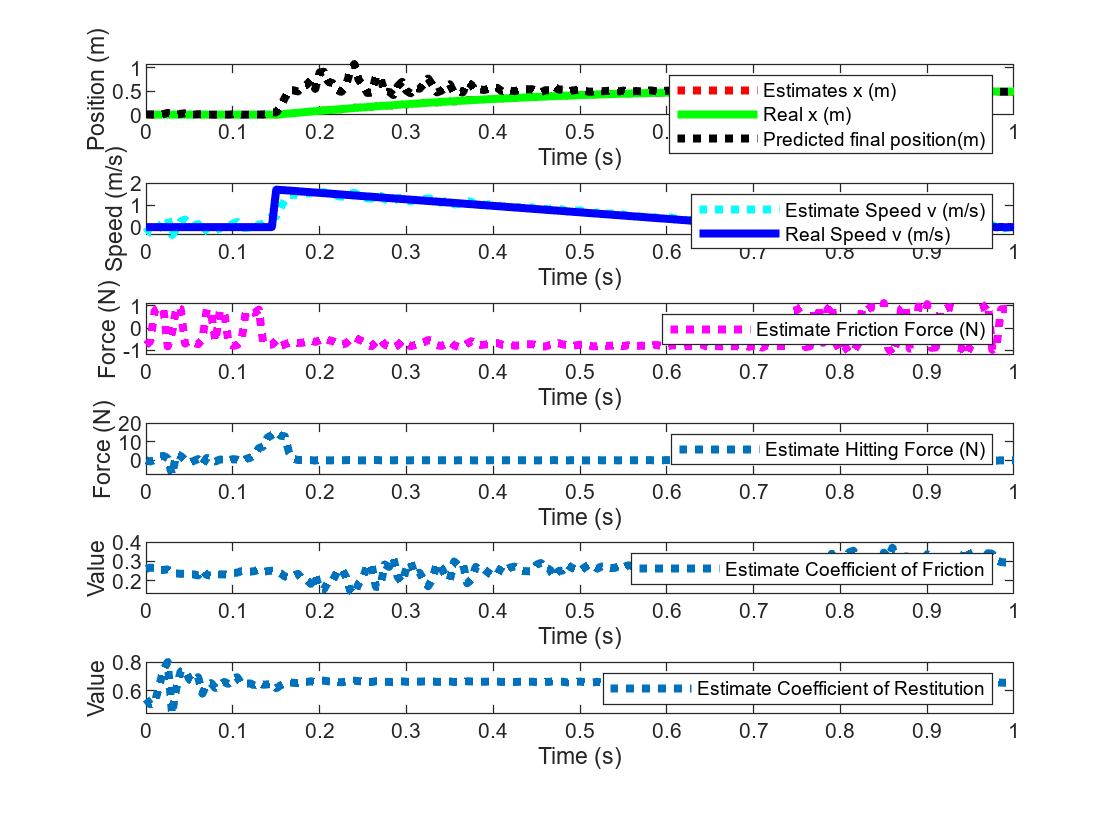


figure

figure

subplot(6,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,3)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,4)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")
subplot(6,1,5)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(6,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Friction")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,6)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(7,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Restitution")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")


%EKF Functions
% By Yi Cao at Cranfield University, 02/01/2008
%
function [x,P]=ekf(x,P,hmeas,z,Q,R,dt,m,mu,phi,sigma_2)
% EKF   Extended Kalman Filter for nonlinear dynamic systems
% [x, P] = ekf(f,x,P,h,z,Q,R) returns state estimate, x and state covariance, P 
% for nonlinear dynamic system:
%           x_k+1 = f(x_k) + w_k
%           z_k   = h(x_k) + v_k
% where w ~ N(0,Q) meaning w is gaussian noise with covariance Q
%       v ~ N(0,R) meaning v is gaussian noise with covariance R
% Inputs:   f: function handle for f(x)
%           x: "a priori" state estimate
%           P: "a priori" estimated state covariance
%           h: fanction handle for h(x)
%           z: current measurement
%           Q: process noise covariance 
%           R: measurement noise covariance
% Output:   x: "a posteriori" state estimate
%           P: "a posteriori" state covariance
%

[x1,A]=jaccsd(x,dt,m,mu,phi,sigma_2);    %nonlinear update and linearization at current state
P=A*P*A'+Q;                 %partial update
H = [1 0 0 0 0 0 0;
     0 0 0 0 1 0 0];
z1 =H*x1;                   %Observation
P12=P*H';                   %cross covariance
% K=P12*inv(H*P12+R);       %Kalman filter gain
% x=x1+K*(z-z1);            %state estimate
% P=P-K*P12';               %state covariance matrix
R=chol(H*P12+R);            %Cholesky factorization
U=P12/R;                    %K=U/R'; Faster because of back substitution
x=x1+U*(R'\(z-z1));         %Back substitution to get state update
P=P-U*U';                   %Covariance update, U*U'=P12/R/R'*P12'=K*P12.
end

function [z,A]=jaccsd(x,dt,m,mu,phi,sigma_2)
% JACCSD Jacobian through complex step differentiation
% [z J] = jaccsd(f,x)
% z = f(x)
% J = f'(x)
%
z=f(x,m,mu,dt,phi,sigma_2);
%x, v, Ff, Fh, d, mu, e
sigma_1_k = ((phi^2*m*(1+x(7))^2)/(2*sigma_2*sqrt(2*pi)));
A=[1 dt (dt^2)/(2*m) (dt^2)/(2*m) 0 0 0;
   0 1 dt/m dt/m 0 0 0;
   0 -m*9.81*x(6)*sign(x(2)) 0 0 0 -m*9.81*sign(x(2)) 0;
   0 0 0 0 -sigma_1_k*abs(x(5)/sigma_2^2)*exp(-x(5)^2 / (2*sigma_2^2)) 0 (2*x(7)+2)*(m*phi^2)/(2*sigma_2*sqrt(2*pi));
   0 0 0 0 1 0 0;
   0 0 0 0 0 1 0;
   0 0 0 0 0 0 1]; 
end

function y=f(x,m,mu,dt,phi,sigma_2)
sigma_1_k = ((phi^2*m*(1+x(7))^2)/(2*sigma_2*sqrt(2*pi)));
y = [x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4))); % x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4)));
     x(2) + (dt/m) * (x(3) + x(4));
     -m*9.81*x(6)*sign(x(2));
     sigma_1_k*exp(-x(5)^2 / (2*sigma_2^2));
     x(5);
     x(6);
     x(7)];% nonlinear state equations

%if (abs(x(2)) <= 1e-2) | (x(5) < 3*sigma_2) %Only if speed is high enough and d latge enough, apply friction ; prevent osicllations around 0 speed
%        y(3) = 0;
%end
end

*Copyright 2021 The MathWorks, Inc.*